# Animating the Puma manipulator performing a task

A factory uses a laser to print different marks on cylinders. With the aim of increasing flexibility, this company decides to robotize this process using a PUMA 560 robot The maximum radius of the manufactured cylinders is 0.10 m and a feeder is used to place them parallel to the robot's xy-plane reference frame and centered at (-0.25, 0.25, -0.5) meters, as shown in the drawing below. To correctly perform the marking task, the laser is used as the robot's end-effector in such a way that its z -axis is orthogonal to the cylindrical surface and its y-axis is pointing in the opposite direction of the z-axis of the robot's base reference frame (refer again to the drawingInitiate  below). To simulate the described task, using the Robotics Toolbox, generate a trajectory for the end-effector of a PUMA robot that executes a circular motion of radius 0.20 m round the manufactured cylinder.

## Initiate the workspace

clc;
clear;
close all;
radius=0.20;
n=200;
INI = transl(-0.25, 0.25,-0.5); %center of the part

## Plot a sketch of the environment of the robot

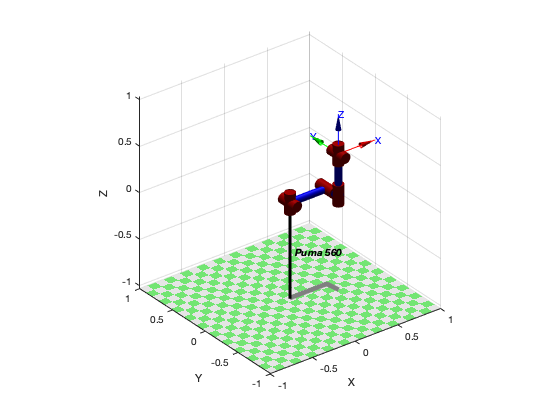

mdl_puma560
p560.plot(qz);

p560.tool=transl(0,0,0)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Drawing the task profile

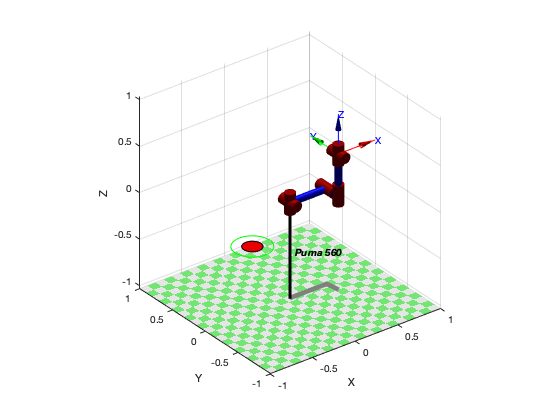

hold on;
circle1 = circle([-0.25 0.25 -0.5], radius);
circle2 = circle([-0.25 0.25 -0.5], 0.5*radius);
plot3(circle1(1,:), circle1(2,:), circle1(3,:),'g','LineWidth',1);
patch(circle2(1,:), circle2(2,:), circle2(3,:),'r');

## Finding the poses to locate the laser. i.e. the {EE}

for i=1:n
Laser_Pose(:,:,i)= INI*trotx(-pi/2)*troty(2*pi*i/n)*transl(0, 0, -radius);
end


## Using the Inverse kinematics to find the joints.

Nex lesson I will explain 'ikine' function.

Q= p560.ikine6s(Laser_Pose, 'run');

## Ploting the result

Experience with 'Zoom', 'View' and 'Worspace' to capture the best perpective.

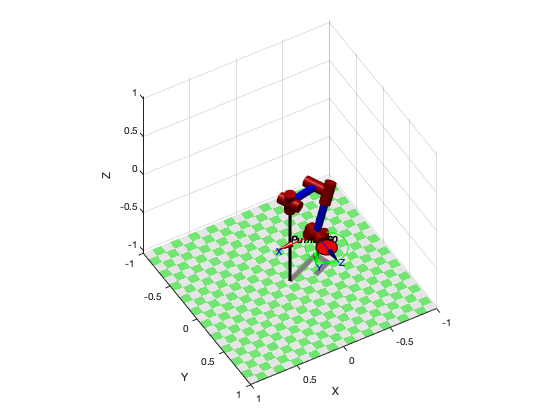

p560.plot(Q,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1])

p560.plot(Q,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1])

clf

## Recording a Video

The RTB will create a video for us.

Setting the enviroment again

Animate: saving video --> Puma_doing_task.mp4 with profile 'MPEG-4'


close all
clf
mdl_puma560
p560.plot(qz);
hold on;
circle1 = circle([-0.25 0.25 -0.5], radius);
circle2 = circle([-0.25 0.25 -0.5], 0.5*radius);
plot3(circle1(1,:), circle1(2,:), circle1(3,:),'g','LineWidth',1);
patch(circle2(1,:), circle2(2,:), circle2(3,:),'r');
p560.plot( Q,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1],...
             'trail','-','jaxes','zoom',2,'movie','Puma_doing_task.mp4')